# Arithmetic and Analytic methods of approximating $\pi$

Yongjun Zhu    93528992

*I hereby confirm that the present report is my own work and that I am not allowed to seek help from anyone else in this project. If any texts or codes from books, papers, the Web or any other sources have been copied or in any other way used, all references have been acknowledged and cited. I am aware that the instructor has the authority to report and investigate any potential academic misconduct in this course, and such misconduct could lead to failing this course. If I have employed any AI models (including but not limited to ChatGPT), I have appropriately and explicitly acknowledged their use in the report whenever the results were generated with the aid of AI.*

## **Integration Approximation Methods:**

Often, we can estimated a desired quatity by finding the area under a curve. Since we will estimate the value $\pi$ and we know that the area formula for a circle is $\pi \cdot r^2$, we can compute the value $\pi$by finding the area of a circle. Algebraicaly, we know that the equation for a circle centered at (a,b) with radius r in the xy-plane is: 

${\left(x-a\right)}^2 +{\left(y-b\right)}^2 =r^2$.

Then we have the simplest case which is a unit circle (a circle with r=1) centered at (0,0) in the form of y is expressed in the term of x: 

$y=\pm \sqrt{1-x^2 }$.

By integrating the quarter sector of the unit circle in the first quardrant whose area is $\frac{\pi }{4}$, with respect to x. We get:

$\int_0^1 \sqrt{1-x^2 }\textrm{dx}=\frac{\pi }{4}$.

By simply taking the integral of this function, we can approximated a quarter of the value of $\pi$, whose accuracy depends on the accuracy of the integration, We can get the approximation of $\pi$ by scalar multiplying $\frac{\pi }{4}$ by 4. Now, we can introduce four numerical methods of integration, which uses the left endpoint, right endpoint, midpoint, and trapezoidal formulas for integration. 

### **Method 1: The Left Endpoint Furmula:**

### 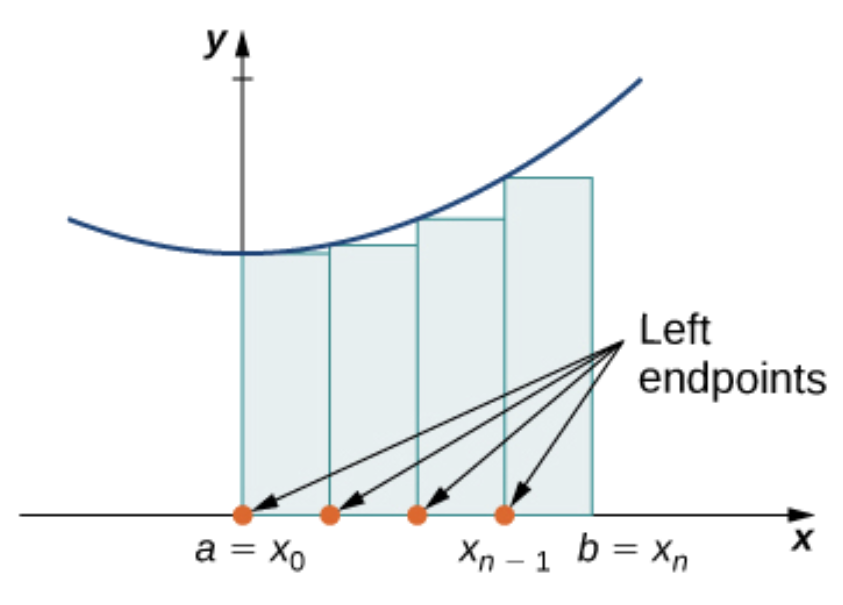

We are going to use the definition of Riemen Sum that instead of using an infinite number of rectangles, we use a finite number of n. 

For methods 1-4, we define the following variables:

Suppose that we have the evenly-spaced partition of interval [a,b], and denote the points as $a=x_0 <x_1 <\ldotp \ldotp \ldotp <x_{n-1} <x_n =b$ and step size $h=\frac{b-a}{n}={x_i -x}_{i-1}$. 

We define the left endpoint formula for approximating an integral by:

$h\sum_{i=1}^n f\left(x_{i-1} \right)=h\left(f\left(x_0 \right)+f\left(x_1 \right)+\ldotp \ldotp \ldotp +f\left(x_{n-1} \right)\right)$.

To implent this formula into the calc_pi(method, n) function, simply input 'left_end_integration' for method and the number of rectangles for n. An example of the right endpoint formula is as below:

format long
calc_pi('left_end_integration', 10000) % 10000 is the number of rectangles we used for the Rieman Sum

ans =    3.141791477611322


### Method 2: The Right Endpoint Formula

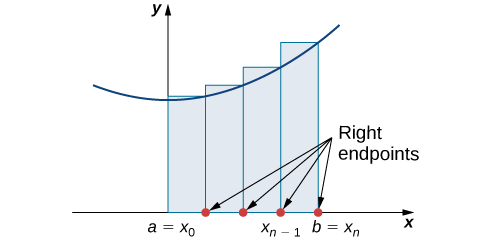

The right endpoint formula for approximating an integral is:

$h\sum_{i=1}^n f\left(x_i \right)=h\left(f\left(x_1 \right)+f\left(x_2 \right)+\ldotp \ldotp \ldotp +f\left(x_n \right)\right)$.

This formula is implented into the calc_pi(method, n) function by inputing 'right_end_integration' as method and the number of rectangles as n. An example of the left endpoint formula is as below:

format long
calc_pi('right_end_integration', 10000) % 10000 is the number of rectangles we used for the Rieman Sum

ans =    3.141391477611323


### Method 3: The Midpoint Formula

The midpoint formula for approximating an integral is:

$h\sum_{i=1}^n f\left(\frac{x_{i-1} +x_i }{2}\right)$.

This formula is implented into the calc_pi(method, n) function by inputing 'midpoint_integration' as method and the number of rectangles as n. An example of the left endpoint formula is as below:

format long
calc_pi('midpoint_integration', 10000) % 10000 is the number of rectangles we used for the Rieman Sum

ans =    3.141592998024640


### Method 4: The Trapezoidal Formula

The midpoint formula for approximating an integral is:

$h\sum_{i=1}^n \frac{f\left(x_{i-1} \right)+f\left(x_i \right)}{2}=h\left(\frac{f\left(x_0 \right)+f\left(x_n \right)}{2}+f\left(x_1 \right)+f\left(x_2 \right)+\ldotp \ldotp \ldotp +f\left(x_{n-1} \right)\right)$.

This formula is implented into the calc_pi(method, n) function by inputing 'trapezoidal_integration' as method and the number of rectangles as n. An example of the left endpoint formula is as below:

format long
calc_pi('trap_integration', 10000) % 10000 is the number of rectangles we used for the Rieman Sum

ans =    3.141591477611323


## Infinite Series Approximation Methods

An infinite series, by definition, is the sum of infinitely many terms with a given initial period. Interestingly, two infinite series in mathematics have values that include the value of π, which I will introduce in their method sections. Defining π as the ratio of a circle's area to its diameter isn't much good. We can't measure the area with enough precision to capture the irrational nature of π.. Instead, infinite series helps us illustrate the analytic which is opposed to arithmetic nature of π .Numerically, we cannot add infinitely many terms; however, we can add a finite, relatively large number of terms to approximate the actual value of the infinite series.

Considering a total of k terms, we formulate the summation of this series by computing:

$S_k =\sum_{n=1}^k f\left(n\right)=f\left(1\right)+f\left(2\right)+\ldotp \ldotp \ldotp +f\left(k\right)$.

Moreover, since this value is not the actual value of the infinite series, the accuracy of the approximated value of $\pi$ will then depend on the number of terms in the series.

### Method 5: First Series about $\pi$

The first series whose value includes $\pi$ is:

$\sum_{n=1}^{\infty } \frac{1}{n^2 }=\frac{\pi^2 }{6}$.

By taking a scalar multiple of 6 and the square root of the summation, I have approximated the value of $\pi$ using this infinite series.

To implent this formula into the calc_pi(method, n) function, simply input 'inf_series_1' for method and the number of terms for n. An example of this method is as below:

format long
calc_pi('inf_series_1', 10000) %10000 terms are used for the summation

ans =    3.141497163947215


### Method 6: Second Series about $\pi$

The second series whose value includes $\pi$ is:

$\sum_{n=1}^{+\infty } \frac{{\left(-1\right)}^{n+1} }{2n-1}=\frac{\pi }{4}=\arctan \left(1\right)$.

By taking a scalar multiple of 4, I have approximated the value of $\pi$ using this infinite series.

To implent this formula into the calc_pi(method, n) function, simply input 'inf_series_2' for method and the number of terms for n. An example of this method is as below:

format long
calc_pi('inf_series_2', 10000) %10000 terms are used for the summation

ans =    3.141492653590034


## Error Estimate for each Method

The accuracy of each method will depend directly on n, whatever n is, the number of rectangles, the number of terms, or the number of coordinates. Now, I want to take a closer look at the relationship between the value of n and the absolute error in approximating π. Note that due to the digital nature of Matlab, the value of π I am comparing here is not the actual value of π, but simply a more precise approximation constructed by Matlab.

I will plot the graph where x-input is n and the y-input is the absolute error when approximation π for each method in the same graph below:

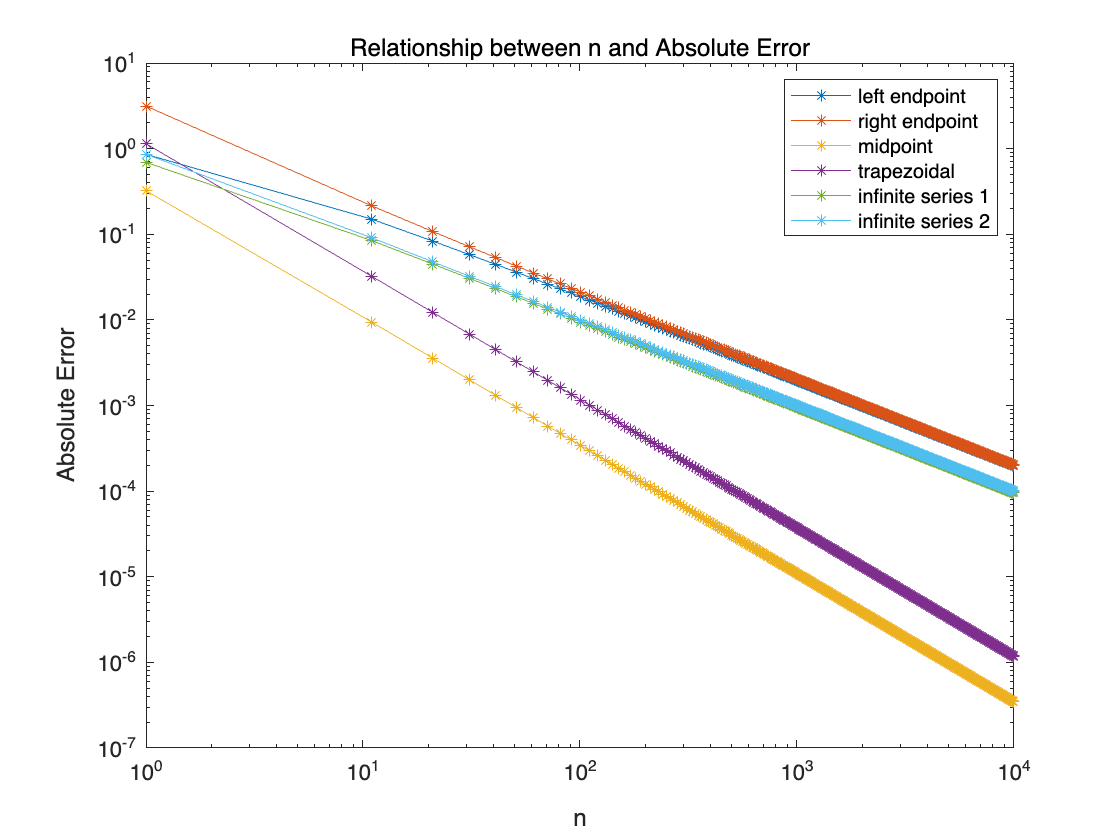

N = 1:10:10000; % n is a linespace from 1 to 10000 with a stepsize of 10. Since the log(0) is not defined, we cannot start from 0.
abs_err = zeros(6, length(N));
for i = 1:length(N)
    abs_err(1,i) = abs(pi - calc_pi('left_end_integration',N(i)));
    abs_err(2,i) = abs(pi - calc_pi('right_end_integration',N(i)));
    abs_err(3,i) = abs(pi - calc_pi('midpoint_integration',N(i)));
    abs_err(4,i) = abs(pi - calc_pi('trap_integration',N(i)));
    abs_err(5,i) = abs(pi - calc_pi('inf_series_1',N(i)));
    abs_err(6,i) = abs(pi - calc_pi('inf_series_2',N(i)));
end
loglog(N,abs_err','*-')
title('Relationship between n and Absolute Error')
legend('left endpoint', 'right endpoint', 'midpoint', 'trapezoidal', 'infinite series 1', 'infinite series 2')
xlabel('n')
ylabel('Absolute Error')

To draw a conclusion: 

For all the methods, as `n` increases, the absolute error decreases. This is expected because a higher number of intervals, terms, or simulations should lead to a more accurate approximation of pi.

Both the numerical integral methods (left end, right end, midpoint, and trapezoidal) and the infinite series methods exhibit a decreasing trend in absolute error with increasing `n`. These methods converge towards the true value of pi as `n` increases.

## Fitting Curve for Error Estimate (helping by Chatgpt)

Our goal here is to further quantify some of the patterns and establish specific relationships within the patterns. In order to do this, we need to fit each of the methods separately, and we will attempt to fit the n versus error data into a single curve.

Since previous attempts to plot n versus error on a logarithmic scale were successful, we should continue to consider fitting on a logarithmic scale. For methods 1-6, this relationship appears to be linear. Therefore, I will try to fit these methods with a first order polynomial.

### Fitting for Method 1

p1 = polyfit(log(abs_err(1,:)),log(N),1)

p1 =    -1.0157    0.5626


To test this linear relationship, I plotted the original data along with the fitted curve below:

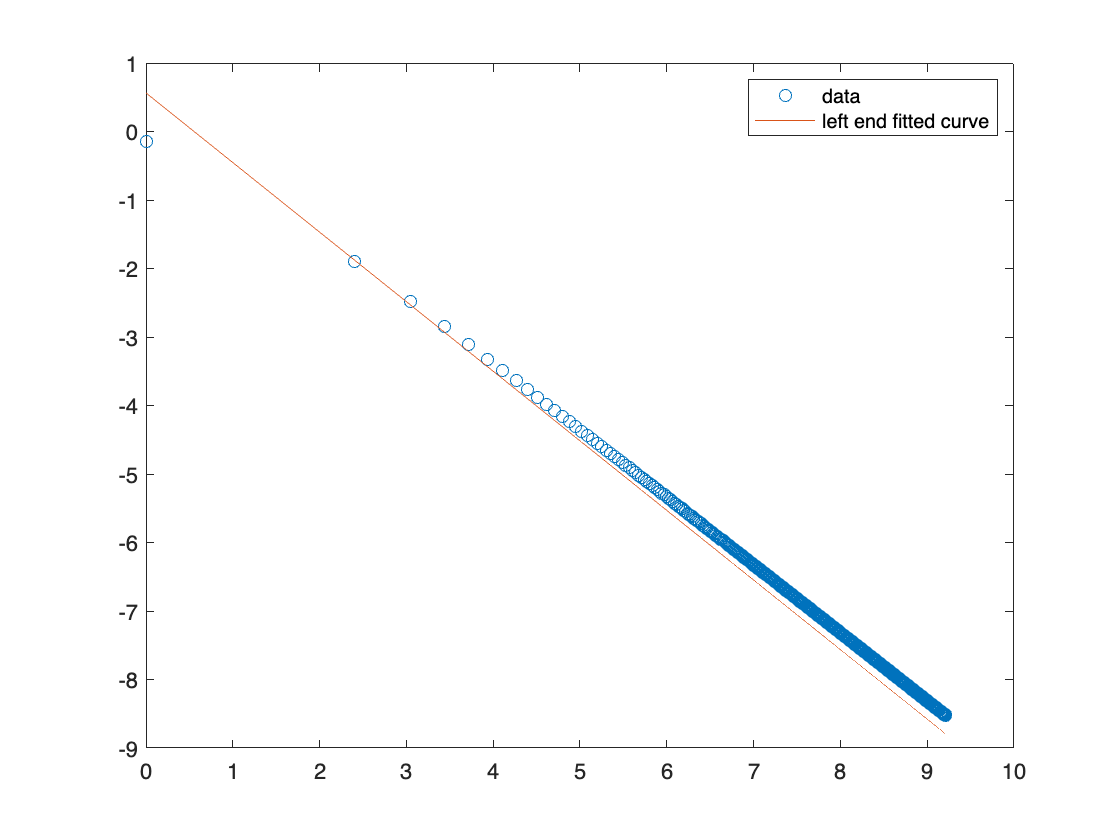

figure
plot(log(N),log(abs_err(1,:)),'o')
hold on
plot(log(N),polyval(p1,log(N)))
hold off
legend('data', 'left end fitted curve')

### Fitting for method 2

p2 = polyfit(log(N),log(abs_err(2,:)),1)

p2 =    -1.0122    0.8052


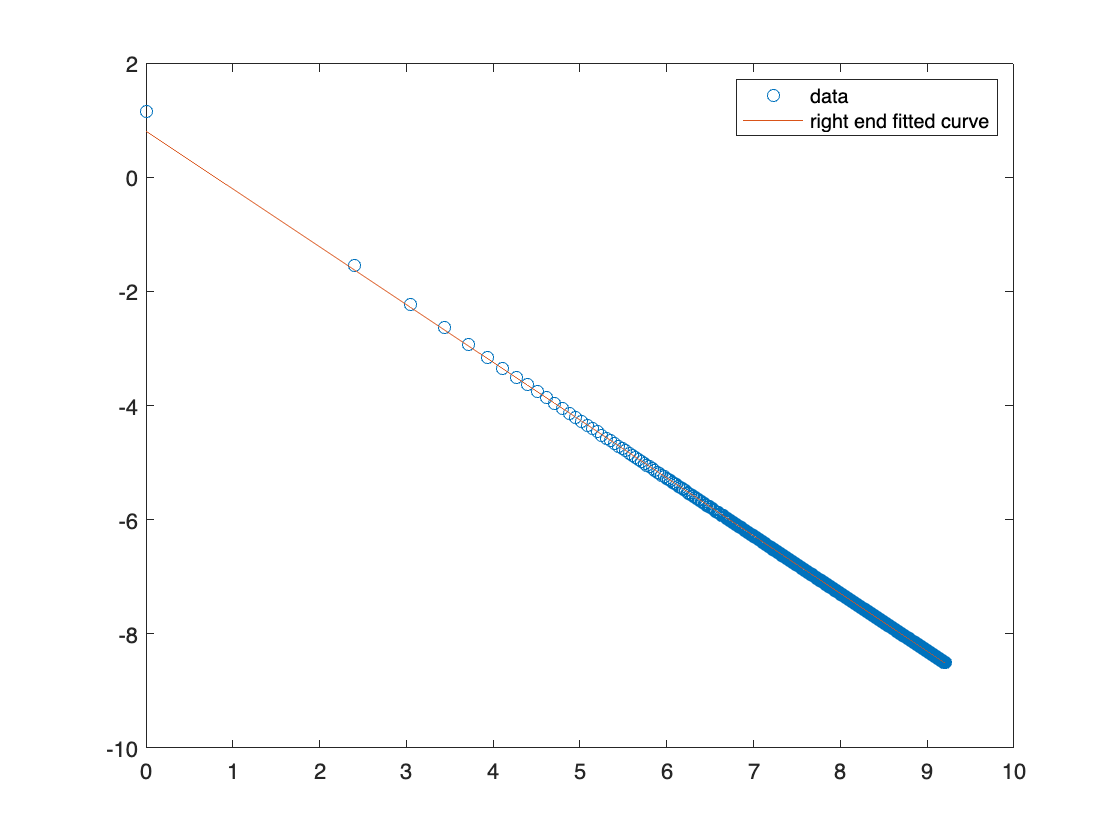

figure
plot(log(N),log(abs_err(2,:)),'o')
hold on
plot(log(N),polyval(p2,log(N)))
hold off
legend('data', 'right end fitted curve')

### Fitting for method 3

p3 = polyfit(log(N),log(abs_err(3,:)),1)

p3 =    -1.4993   -1.0713


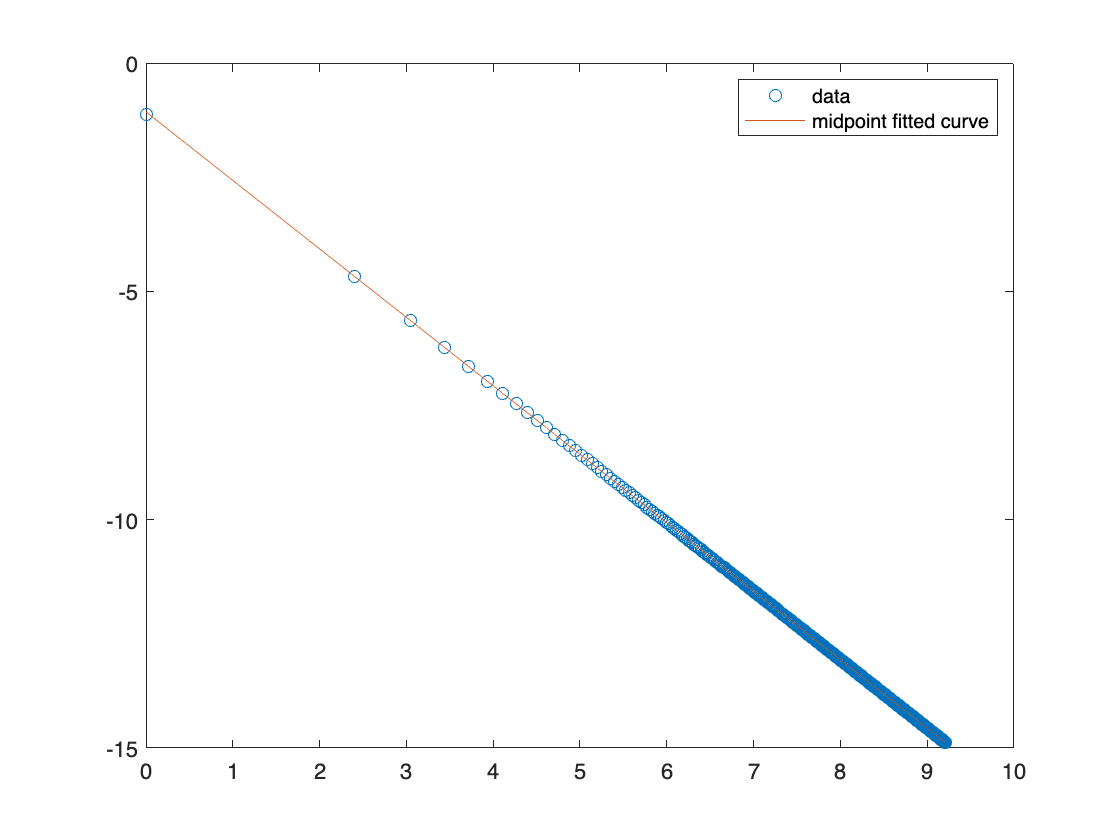

figure
plot(log(N),log(abs_err(3,:)),'o')
hold on
plot(log(N),polyval(p3,log(N)))
hold off
legend('data', 'midpoint fitted curve')

### Fitting for method 4

p4 = polyfit(log(N),log(abs_err(4,:)),1)

p4 =    -1.4997    0.1596


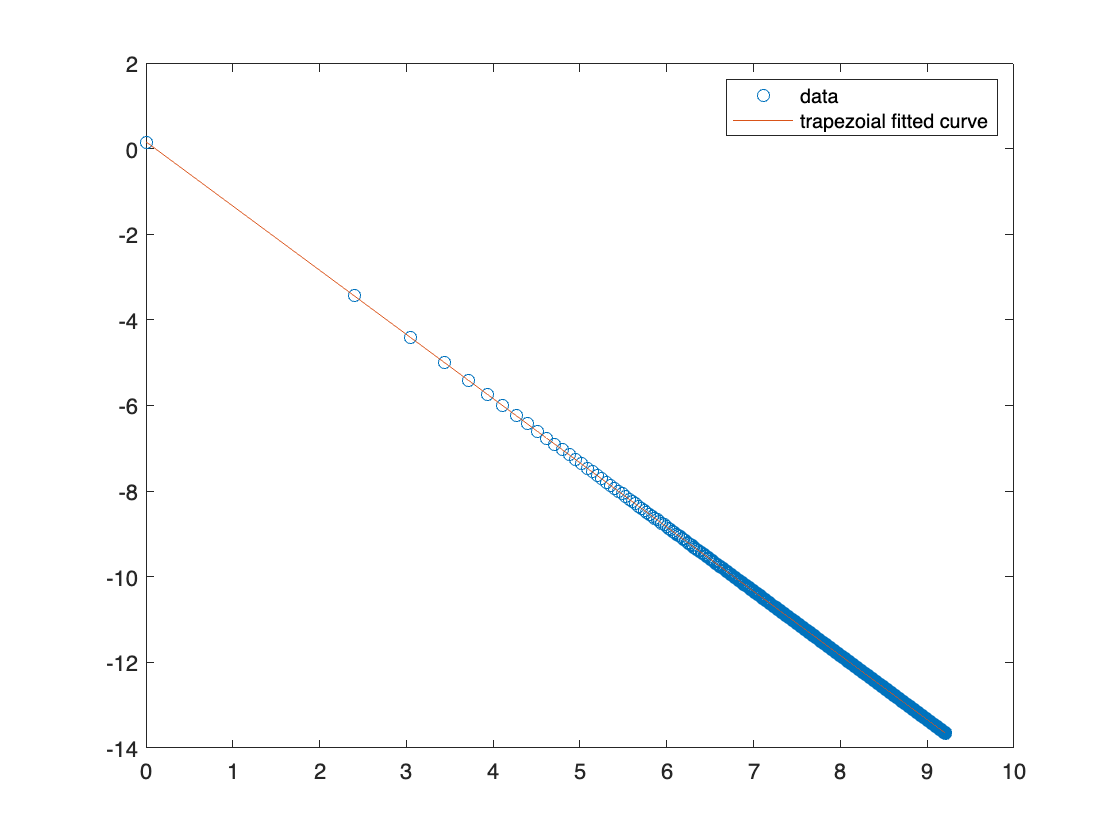

figure
plot(log(N),log(abs_err(4,:)),'o')
hold on
plot(log(N),polyval(p4,log(N)))
hold off
legend('data', 'trapezoial fitted curve')

### Fitting for method 5

p5 = polyfit(log(N),log(abs_err(5,:)),1)

p5 =    -0.9968   -0.0731


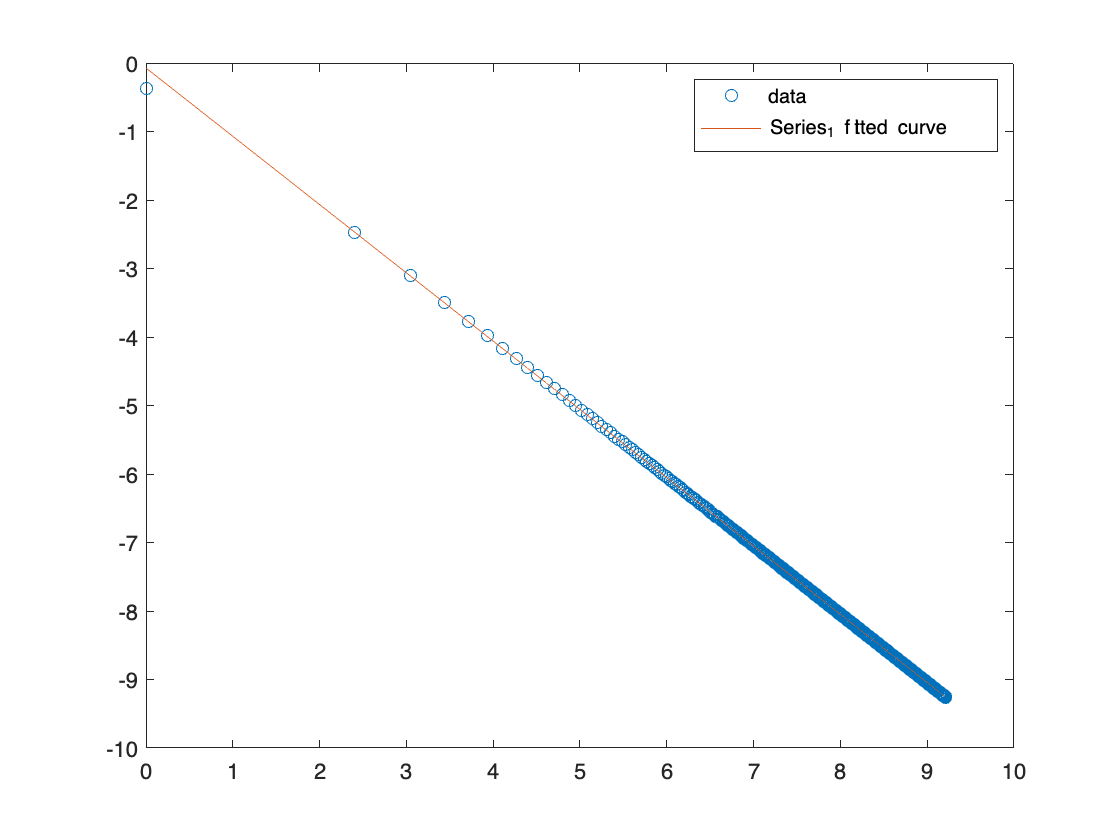

figure
plot(log(N),log(abs_err(5,:)),'o')
hold on
plot(log(N),polyval(p5,log(N)))
hold off
legend('data', 'Series_1 fitted curve')

### Fitting for method 6

p6 = polyfit(log(N),log(abs_err(6,:)),1)

p6 =    -0.9988   -0.0103


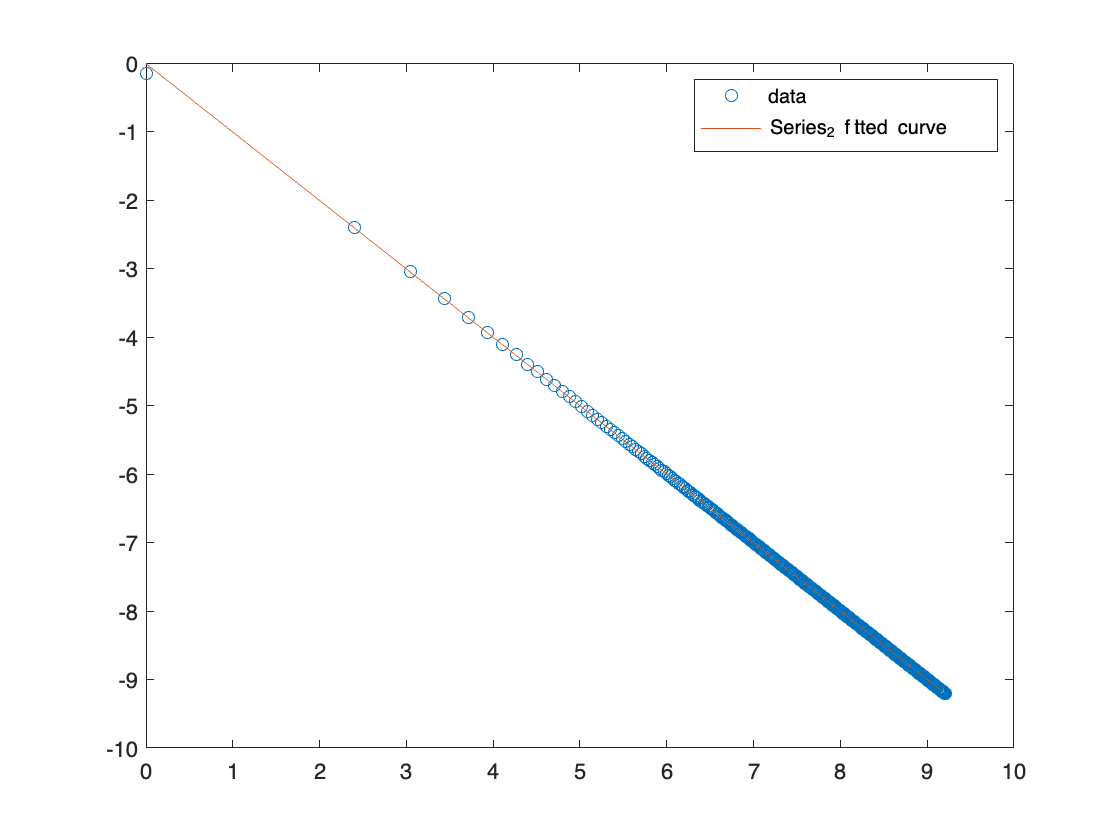

figure
plot(log(N),log(abs_err(6,:)),'o')
hold on
plot(log(N),polyval(p6,log(N)))
hold off
legend('data', 'Series_2 fitted curve')

Conclusion:

As shown by the close fit between the linear fit curve and the data (on a logarithmic scale), we can see a clear linear trend in the data from the graphs of methods 1-6. 

function output = calc_pi(method,n)
%The calc_pi(method,n) function outputs a numerical calculation of pi given an input of a 
%specific "method" and it is respective to "n". The "method" input includes 6 possible 
%choices: 4 integration approximation methods and 2 infinite series approximation methods. 
% To call the function using these methods, the user should input "method" == "left_end_integration",
%"right_end_integration", "midpoint_integration", "trapezoidal_integration", "inf_series_1", 
%or "inf_series_2". Respective to the order of the 6 methods mentioned previously.
% The input n denotes the number of rectangles in the integration methods and the total terms in the infinite series method.
h = (1-0)/n;
x = 0:h:1;
x_mid = 0+h/2:h:1;
    switch method
        case 'left_end_integration'
            f_val = (1-x.^2).^(0.5);
            output = 4*h*sum(f_val(1:end-1));
        case 'right_end_integration' 
            f_val = (1-x.^2).^(0.5);
            output = 4*h*sum(f_val(2:end));
        case 'midpoint_integration'
            f_val = (1-x_mid.^2).^(0.5);
            output = 4*h*sum(f_val);
        case 'trap_integration'
            f_val = (1-x.^2).^(0.5);
            output = 4*0.5*h*(sum(f_val(1:end-1))+sum(f_val(2:end)));
        case 'inf_series_1'
            v = 1:n;
            f = 1./v.^2;
            tot = 0;
                for x = v
                    tot = tot + f(x);
                end
            output = (6*tot)^(0.5);
        case 'inf_series_2'
            v = 1:n;
            f = (-1).^(v+1)./(2*v-1);
            tot = 0;
                for x = v
                    tot = tot + f(x);
                end
            output = 4*tot;
    end    
end